# 3D Discrete Operators

clear, close all, clc
set_defaults()

## 3D staggered grid

Due to the internal logic of the Matlab functions meshgrid() and reshape() it is best to order the number the unknowns/cells/faces/dof's in the 3D grid in y-direction first, then in x-direction and then z direction.

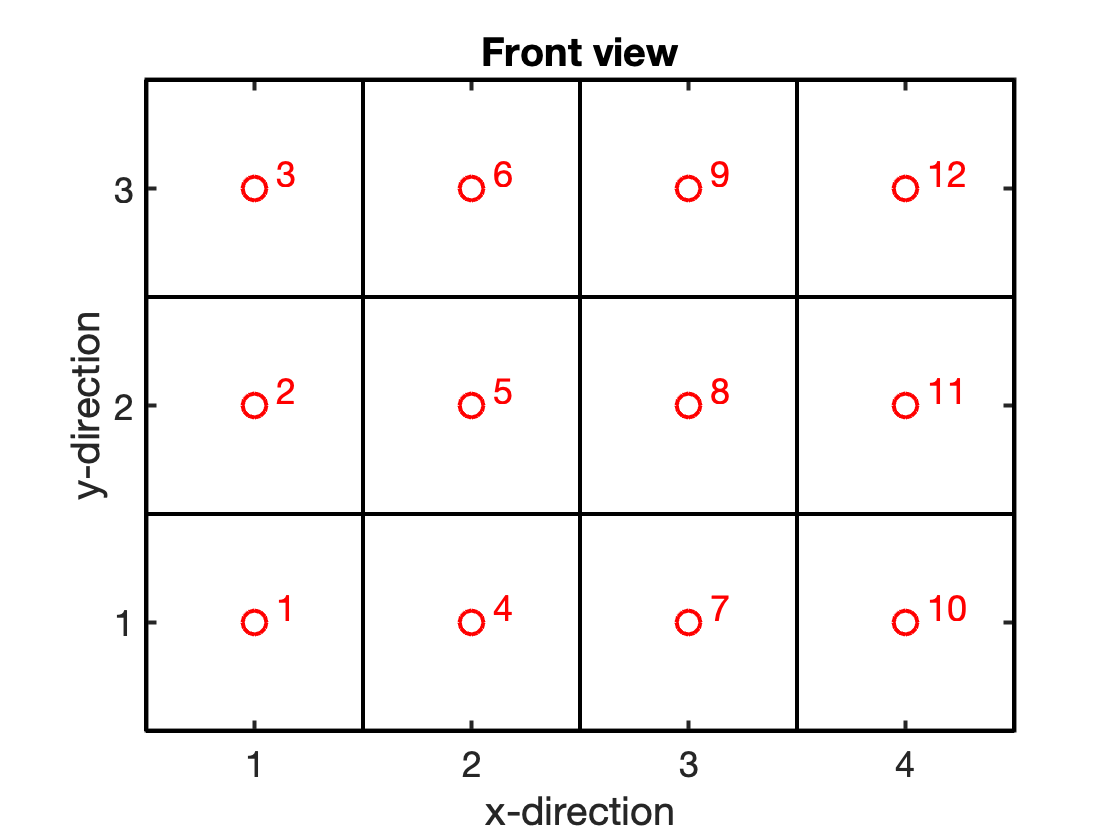

Nx = 4; Ny = 3; Nz = 2;
plot_grid(Nx,Ny)

On this grid we need a two discrete operatore:

- Discrete divergence: `D`` = [``Dx``,``Dy``]`

- Discrete gradient:     **G** = [**Gx**;**Gy**]

## Assembly of discrete divergence

The rank-2 tensors `Dx,` `Dy ``and` `Dz` are block matrices that are composed of

- 1D divergence and gradient operators

- (scaled) Indentity matrices

- zeros

These matrices can therefore be assembled simply and efficiently using tensor/Kronecker products. 

Last class we have shown that the 2D and then 3D operators can be defirned in terms of the 1D operators as follows

**x-direction discrete divergence matrix:**


$$\underline{\underline{\textbf{Dx}^2}} =  \underline{\underline{\textbf{Dx}^1}} \otimes \underline{\underline{\textbf{Iy}}}  \\
\underline{\underline{\textbf{Dx}^3}} = \underline{\underline{\textbf{Iz}}}   \otimes \underline{\underline{\textbf{Dx}^2}} = \underline{\underline{\textbf{Iz}}}  \otimes (\underline{\underline{\textbf{Dx}^1}} \otimes \underline{\underline{\textbf{Iy}}})$$


**y-direction discrete divergence matrix:**


$$\underline{\underline{\textbf{Dy}^2}} = \underline{\underline{\textbf{Ix}}}  \otimes \underline{\underline{\textbf{Dy}^1}}  \\
\underline{\underline{\textbf{Dy}^3}} = \underline{\underline{\textbf{Iz}}}   \otimes \underline{\underline{\textbf{Dy}^2}} = \underline{\underline{\textbf{Iz}}}  \otimes (\underline{\underline{\textbf{Ix}}}  \otimes \underline{\underline{\textbf{Dy}^1}} )$$


**z-direction discrete divergence matrix: ***(little trickier than others!)*


$$\underline{\underline{\textbf{Dz}^3}}  = \underline{\underline{\textbf{Dz}^1}} \otimes (\underline{\underline{\textbf{Ix}}}  \otimes \underline{\underline{\textbf{Iy}}}  )$$


Therefore they can be constructed as:

- `Dx`` = kron(``Iz,``kron(``Dx``,``Iy``));`

- `Dy`` = kron(``Iz,``kron(``Ix``,``Dy``));`

- `Dz`` = kron(``Dz,``kron(``Ix``,``Iy``));`

where `Ix,` `Iy ``and`` Iz` are Nx by Nx, Ny by Ny and Nz by Nz identity matrices, respectively.

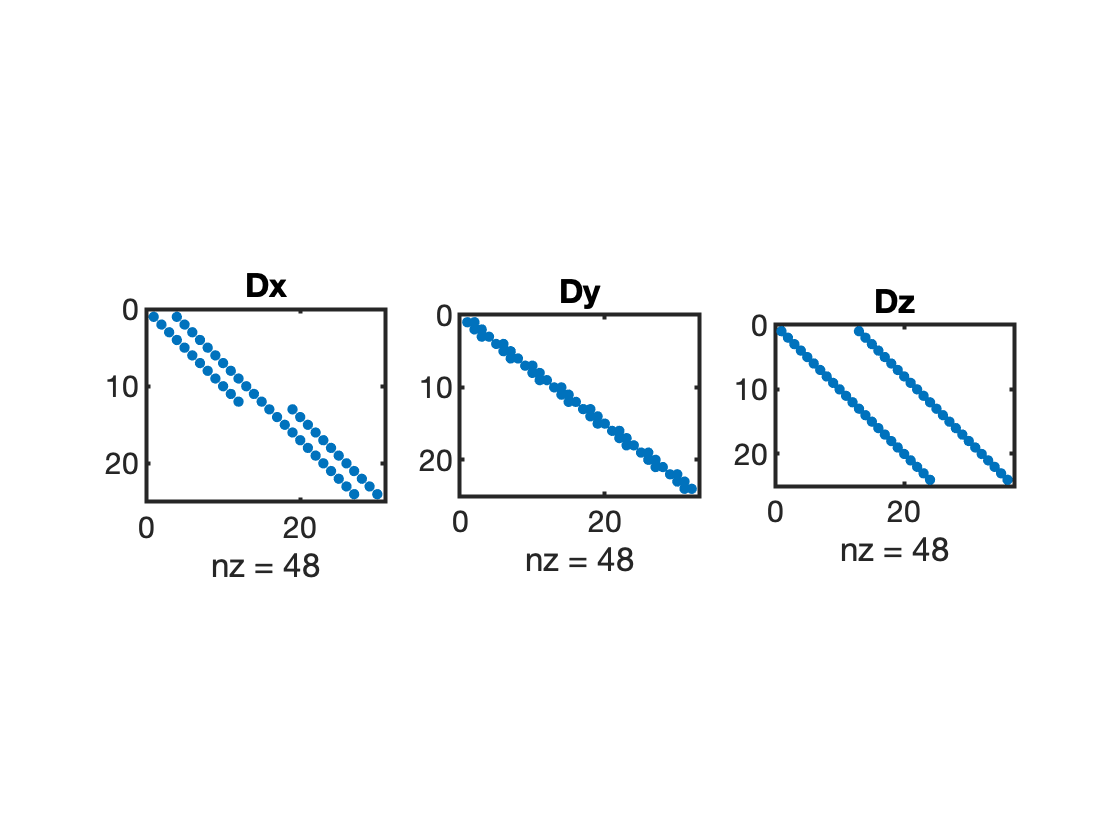

Grid.xmin = 0; Grid.xmax = 1; Grid.Nx = Nx;
Grid.ymin = 0; Grid.ymax = 1; Grid.Ny = Ny;
Grid.zmin = 0; Grid.zmax = 1; Grid.Nz = Nz;
Grid = build_grid3D(Grid);

%Build Identities
Ix = speye(Nx);
Iy = speye(Ny);
Iz = speye(Nz);

% Build 3D Dx matrix
Dx = spdiags([-ones(Nx,1) ones(Nx,1)]/Grid.dx,[0 1],Nx,Nx+1);
Dx = kron(Iz,kron(Dx,Iy));

% Build 3D Dy matrix
Dy = spdiags([-ones(Ny,1) ones(Ny,1)]/Grid.dy,[0 1],Ny,Ny+1);
Dy = kron(Iz,kron(Ix,Dy));

% Build 3D Dz matrix
Dz = spdiags([-ones(Nz,1) ones(Nz,1)]/Grid.dz,[0 1],Nz,Nz+1);
Dz = kron(Dz,kron(Ix,Iy));

% Full 3D discrete divergence matrix
D = [Dx,Dy,Dz];

subplot 131
spy(Dx), title 'Dx'
subplot 132
spy(Dy), title 'Dy'
subplot 133
spy(Dz), title 'Dz'

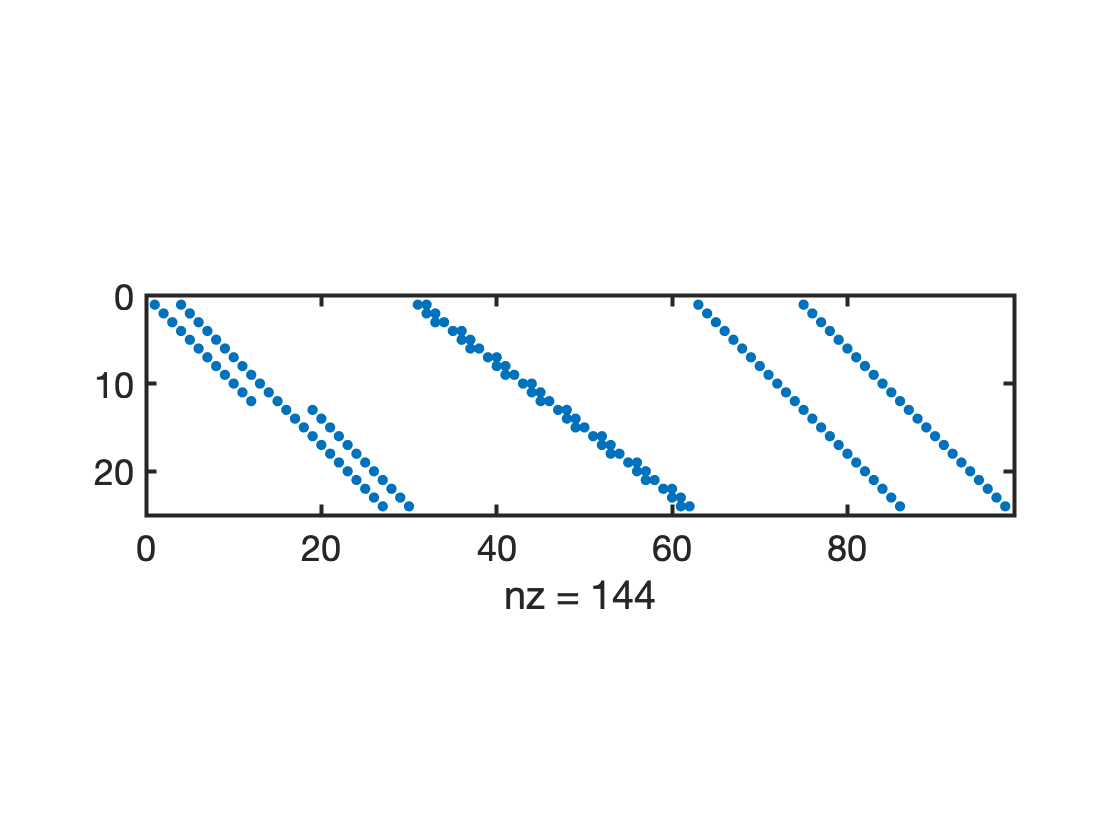


figure
spy(D)

Note, that 3D operators can be assembled similarly by applying the tensor product to the 2D matrices and `Iz`!

## Discrete gradient

While it is straight forward to assemble the gradients directly, it is even more convenient to recognize that the gradient is the adjoint operator of the divergence in the interior of the domain, but has natural boundary conditions (zero gradient) on the exterior. Hence, we obtain `G` as in 1D:

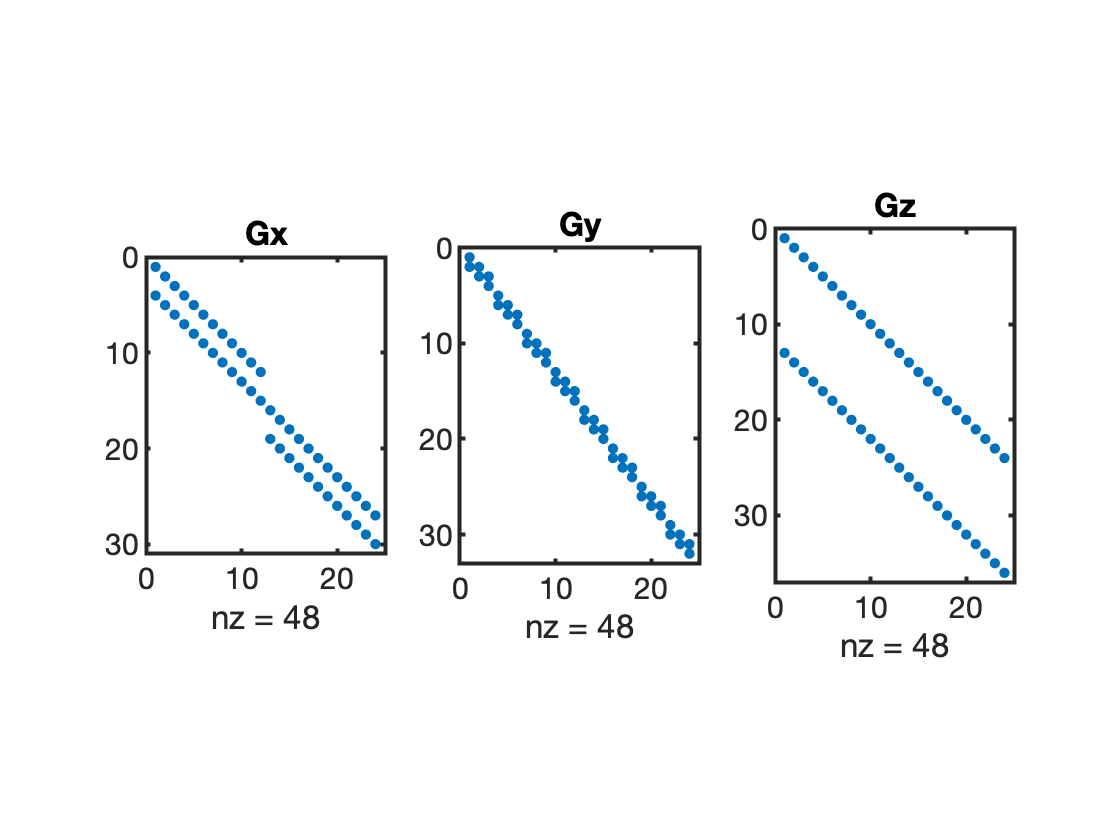

% ADJOINT IN INTERIOR
G = -D';  

% NATUAL BC's ON EXTERIOR 
% collect all exterior faces
%{
commented because of the issues with boundary faces
dof_f_bnd = [Grid.dof_f_xmin; Grid.dof_f_xmax;... 
             Grid.dof_f_ymin; Grid.dof_f_ymax];
% set gradient to zero
G(dof_f_bnd,:) = 0;
%}
% plot
figure
subplot 131
spy(G(1:Grid.Nfx,:)), title 'Gx'
subplot 132
spy(G(Grid.Nfx+1:Grid.Nfx+Grid.Nfy,:)), title 'Gy'
subplot 133
spy(G(Grid.Nfx+Grid.Nfy+1:Grid.Nf,:)), title 'Gz'

## 3D discrete Laplacian

As in 1D and 2D the discrete Laplacian in 3D is simply the product of `D` and `G`:

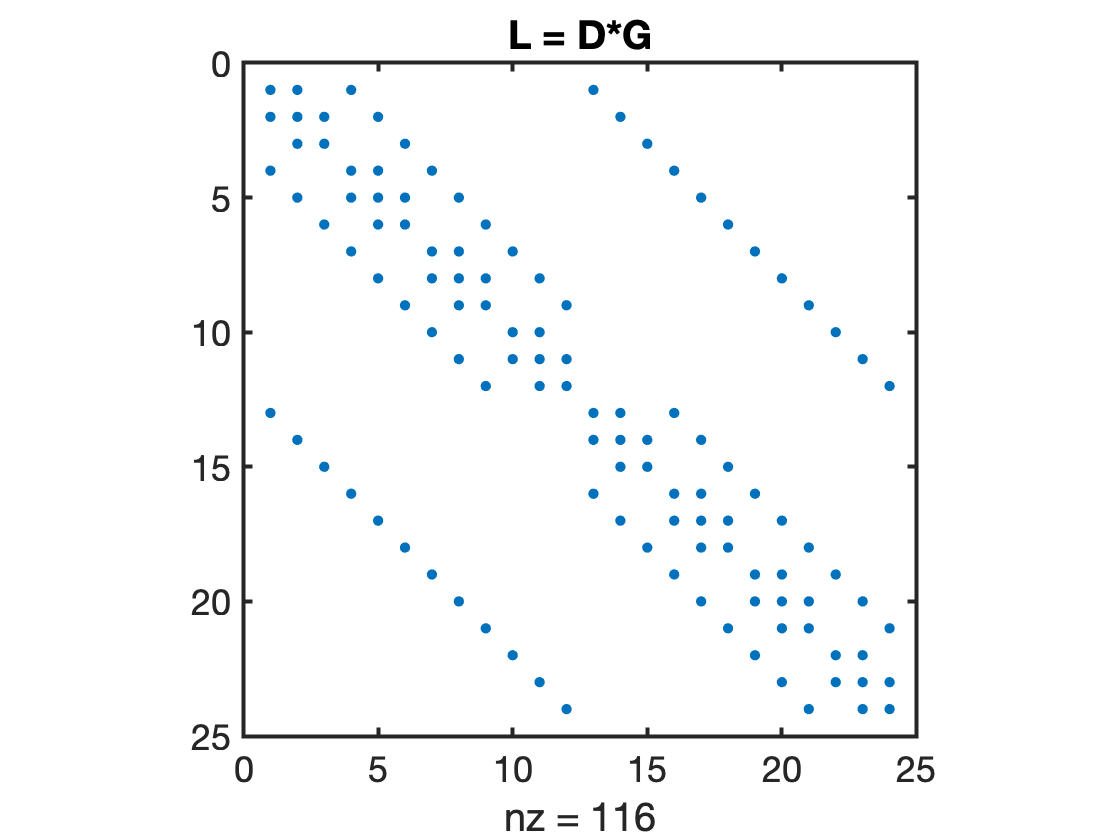

L = -D*G;
figure
spy(L), title 'L = D*G'

# *Testing the discrete divergence and gradients*

Grid.xmin = 0; Grid.xmax = 3; Grid.Nx = 100;
Grid.ymin = 0; Grid.ymax = 3; Grid.Ny = 100;
Grid.zmin = 0; Grid.zmax = 3; Grid.Nz = 100;

Grid = build_grid3D(Grid);
[D,G,C,I,M] = build_ops3D(Grid); L = D*G;

## Differentiating a function that statisfies the natural BC's

%{
f = @(x,y,z) exp(cos(2*pi*x));
df = @(x,y,z) -2*pi*f(x,y,z).*sin(2*pi*x);
d2f = @(x,y,z) -2*pi^2*exp(cos(2*pi*x)).*(2*cos(2*pi*x)+cos(4*pi*x)-1);
%}

f = @(x,y,z) exp(cos(2*pi*x)).*exp(cos(2*pi*y)).*exp(cos(2*pi*z));
df = @(x,y,z) -2*pi*f(x,y,z).*[sin(2*pi*x); sin(2*pi*y) ; sin(2*pi*z)];
d2f = @(x,y,z) 4*pi^2.*f(x,y,z).*[(sin(2*pi*x)).^2 - cos(2*pi*x) + ...
                                  (sin(2*pi*y)).^2 - cos(2*pi*y) + ...
                                  (sin(2*pi*z)).^2 - cos(2*pi*z)];


[X,Y,Z] = meshgrid(Grid.xc,Grid.yc,Grid.zc);

soln = f(X(:),Y(:),Z(:));
SOLN_reshaped = reshape(soln,Grid.Ny,Grid.Nx,Grid.Nz);
SOLN_original = f(X,Y,Z);

%numerical gradient
gradient_numerical  = G * soln(:);

laplacian_numerical = D * G * soln(:); 
laplacian_numerical  = reshape(laplacian_numerical,Grid.Ny,Grid.Nx,Grid.Nz);

%analytical laplacian
xa = linspace(Grid.xmin,Grid.xmax,1e2);
ya = linspace(Grid.ymin,Grid.ymax,1e2);

#############CHECKS ######################

za = linspace(Grid.zmin,Grid.zmax,1e2);

Solutions

[Xa,Ya,Za] = meshgrid(xa,ya,za);

Difference of vectors

laplacian_analytical = d2f(X,Y,Z);

ans = 0

Difference of vector sizes

fprintf('#############CHECKS ######################')

ans =      0     0     0


fprintf('Solutions')
fprintf('Difference of vectors')

Laplacian

norm(SOLN_original(:) - SOLN_reshaped(:)) %check if same or not

Difference of vectors

fprintf('Difference of vector sizes')

ans = 1.7828e+06

size(SOLN_original) - size(SOLN_reshaped)

Difference of vector sizes

ans =      0     0     0


fprintf('Laplacian')

##########################################

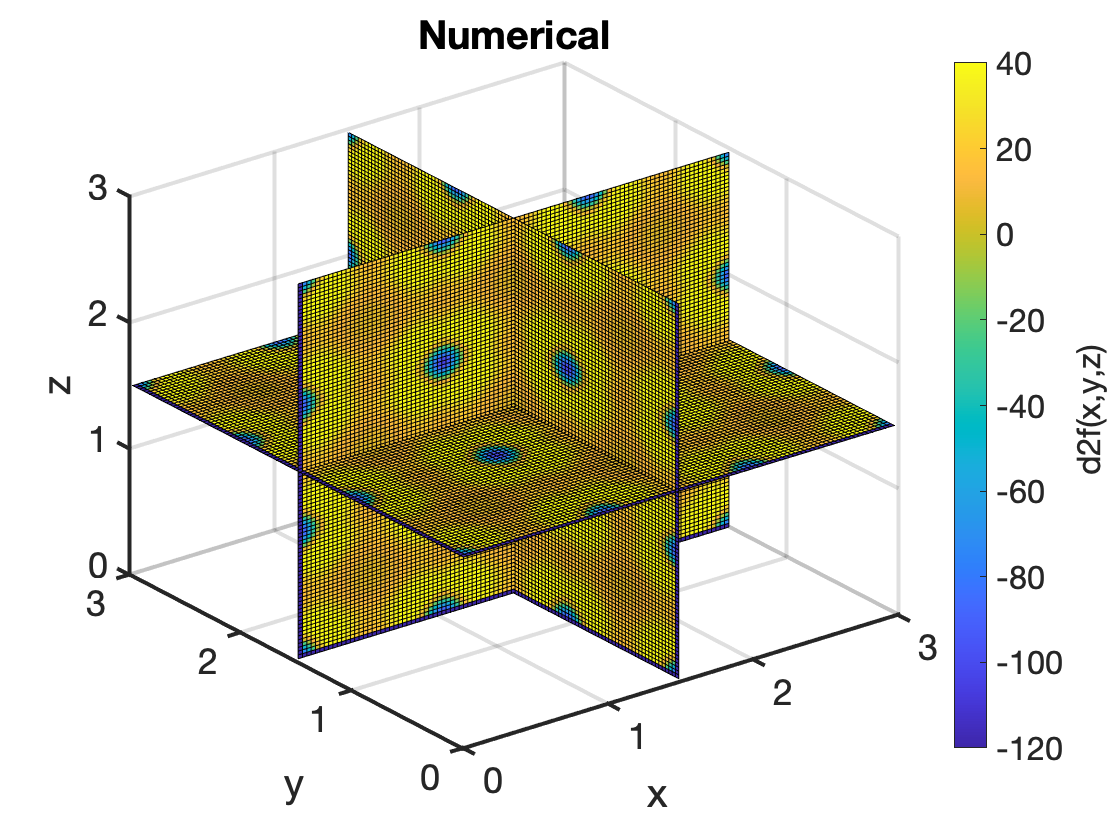

fprintf('Difference of vectors')
norm(laplacian_numerical(:) - laplacian_analytical(:)) %check if same or not
fprintf('Difference of vector sizes')
size(laplacian_numerical) - size(laplacian_numerical)
fprintf('##########################################')


%Plotting
%numerical
figure()
xslice = [(Grid.xmax-Grid.xmin)/2];                               % define the cross sections to view
yslice = [(Grid.ymax-Grid.ymin)/2];
zslice = ([(Grid.zmax-Grid.zmin)/2]);

slice(X, Y, Z, laplacian_numerical, xslice, yslice, zslice)    % display the slices

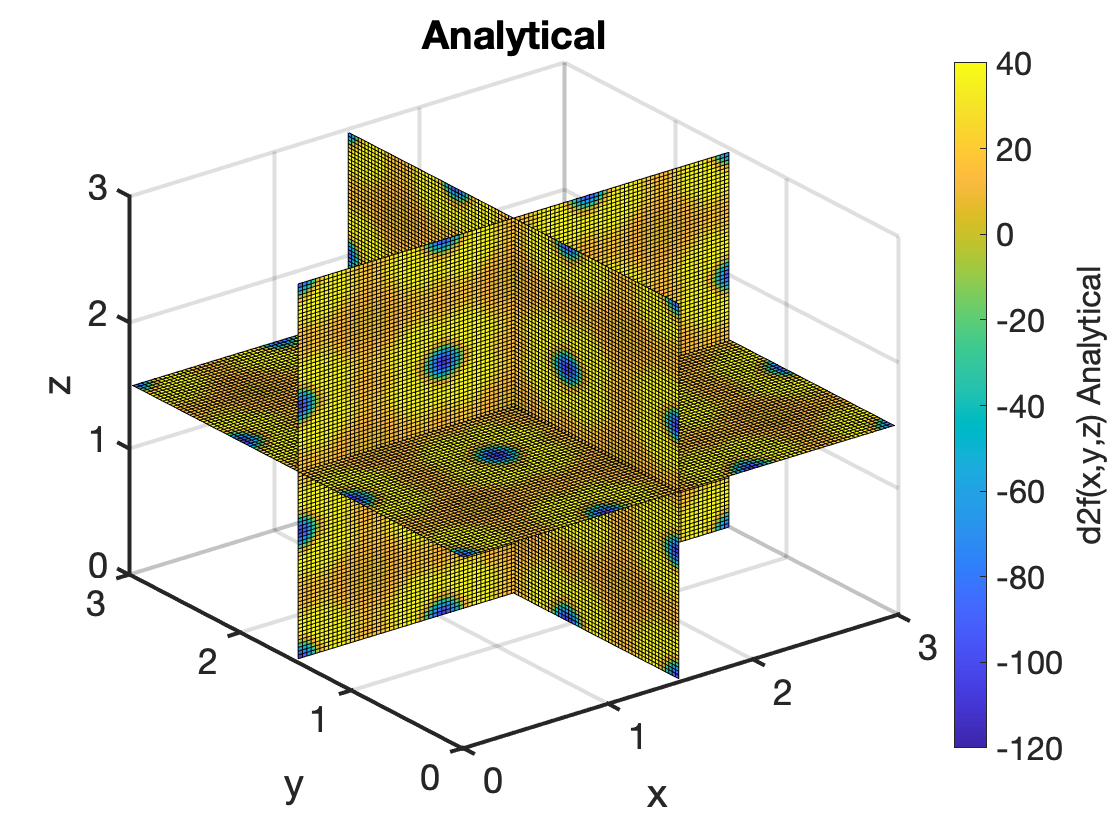

xlabel 'x', ylabel 'y', zlabel 'z'
cb = colorbar;                                  % create and label the colorbar
title 'Numerical'
cb.Label.String = 'd2f(x,y,z) ';
caxis([-120 40])

%analytical
figure()
xslice = [(Grid.xmax-Grid.xmin)/2];                               % define the cross sections to view
yslice = [(Grid.ymax-Grid.ymin)/2];
zslice = ([(Grid.zmax-Grid.zmin)/2]);

slice(X, Y, Z, laplacian_analytical, xslice, yslice, zslice)    % display the slices

xlabel 'x', ylabel 'y', zlabel 'z'
cb = colorbar;                                  % create and label the colorbar
title 'Analytical'
cb.Label.String = 'd2f(x,y,z) Analytical';
caxis([-120 40])


%{
xa = linspace(0,3,3e2);
figure(2)
subplot 311
plot(xa,f(xa),'r',x,f(x),'bo','markerfacecolor','w','markersize',6)
xlabel 'x', ylabel 'f'
legend('analytical','numerical')

subplot 312
plot(xa,dfdx(xa),'r',x,D*f(x),'bo','markerfacecolor','w','markersize',6)
xlabel 'x', ylabel 'df/dx'

subplot 313
plot(xa,d2fdx2(xa),'r',x,D*D*f(x),'bo','markerfacecolor','w','markersize',6)
xlabel 'x', ylabel 'd^2f/dx^2'
ylim([-100 50])
%}

# Auxillary functions

## set_defaults()

function [] = set_defaults()
set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);
end

## plot_grid()

function [] = plot_grid(Nx,Ny)
N = Nx*Ny;

x = 1:Nx;
y = 1:Ny;
dof = 1:N;

[X,Y] = meshgrid(x,y);

DOF = reshape(dof,Ny,Nx);

plot([.5 Nx+.5 Nx+.5 .5 .5],[.5 .5 Ny+.5 Ny+.5 .5],'k'), hold on
title 'Front view'
for i=1:Nx
    plot([x(i)+.5 x(i)+.5],[.5 Ny+.5],'k-')
    for j=1:Ny
        plot([.5 Nx+.5],[y(j)+.5 y(j)+.5],'k-')
        plot(X(j,i),Y(j,i),'ro','markerfacecolor','w')
        text(X(j,i)+.1,Y(j,i)+.07,num2str(DOF(j,i)),'fontsize',18,'color','r')
    end
end
set(gca,'xtick',[1:Nx],'ytick',[1:Ny])
axis equal tight 
xlabel 'x-direction'
ylabel 'y-direction'
end